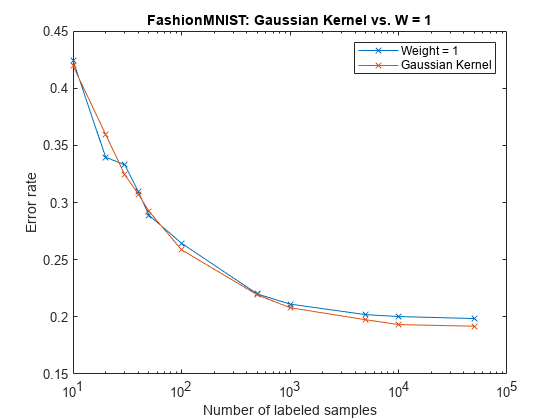

load('fmW1.mat');

unitweight= 1-mean(accuracy,2);

load('fashionmnistresults.mat');

gaussian = 1-mean(accuracy,2);


x = [10,20,30,40,50,100,500,1000,5000,10000,50000];

semilogx(x,unitweight,'-x',x,gaussian,'-x')
title('FashionMNIST: Gaussian Kernel vs. W = 1')
xlabel('Number of labeled samples')
ylabel('Error rate')
legend('Weight = 1','Gaussian Kernel')

print(gcf,'-dpng','FMWeights.png')